% (x^2+y^2+y)*dx+(2*x*y+x+exp(y))*dy=0
% y(0)=0

% 1)
clear
% y'=-(x^2+y^2+y)/(2*x*y+x+exp(y))
syms x y(x) C
eqn=(x^2+y^2+y)+(2*x*y+x+exp(y))*diff(y)

$$eqn(x) = y\left(x\right)+\left(x+{\mathrm{e}}^{y\left(x\right)}+2\,x\,y\left(x\right)\right)\,\frac{\partial }{\partial x}y\left(x\right)+{y\left(x\right)}^{2}+x^{2}$$

cond=y(0)==0

$$cond = y\left(0\right)=0$$

ySol=dsolve(eqn,cond)

$$ySol = \mathrm{solve}\left(\frac{x^{3}}{3}+\left(y^{2}+y\right)\,x+{\mathrm{e}}^{y}-1,y\right)$$

% solve(exp(y) + x*y*(y + 1) == 1 - x^3/3, y)
eq1= exp(y) + x*y*(y + 1) + x^3/3 - 1

$$eq1(x) = {\mathrm{e}}^{y\left(x\right)}+\frac{x^{3}}{3}+x\,y\left(x\right)\,\left(y\left(x\right)+1\right)-1$$


% 2)
syms x y dx dy C
eq1=(x^2+y^2+y)*dx+(2*x*y+x+exp(y))*dy

$$eq1 = \mathrm{dx}\,\left(x^{2}+y^{2}+y\right)+\mathrm{dy}\,\left(x+{\mathrm{e}}^{y}+2\,x\,y\right)$$

cfs=coeffs(eq1,[dy dx])

$$cfs = \left(\begin{array}{cc} x^{2}+y^{2}+y & x+{\mathrm{e}}^{y}+2\,x\,y \end{array}\right)$$

P=cfs(1), Q=cfs(2)

$$P = x^{2}+y^{2}+y$$

$$Q = x+{\mathrm{e}}^{y}+2\,x\,y$$

f=simplify(diff(P,y)-diff(Q,x))

$$f = 0$$

% dPy==dQx

% U(x,y)
% dUx=P, dUy=Q
syms C(y)
U=int(P,x)+C(y)

$$U = \frac{x^{3}}{3}+\left(y^{2}+y\right)\,x+C\left(y\right)$$

% C(y) + x*(y^2 + y) + x^3/3
dUy=diff(U,y)

$$dUy = \frac{\partial }{\partial y}C\left(y\right)+x\,\left(2\,y+1\right)$$

% x*(2*y + 1) + diff(C(y), y)
dCy=simplify(dUy-Q)

$$dCy = \frac{\partial }{\partial y}C\left(y\right)-{\mathrm{e}}^{y}$$

% diff(C(y), y) - exp(y) => dCy=exp(y) => C(y)=exp(y)
% exp(y) + x*(y^2 + y) + x^3/3 = C1
syms C1
eq1=exp(y) + x*(y^2 + y) + x^3/3 - C1

$$eq1 = \frac{x^{3}}{3}+\left(y^{2}+y\right)\,x-C_{1}+{\mathrm{e}}^{y}$$

eq2=subs(eq1,[x y],[0 0])

$$eq2 = 1-C_{1}$$

% C1=1
% exp(y) + x*(y^2 + y) + x^3/3 = 1
eq2=exp(y) + x*(y^2 + y) + x^3/3 - 1

$$eq2 = \frac{x^{3}}{3}+\left(y^{2}+y\right)\,x+{\mathrm{e}}^{y}-1$$

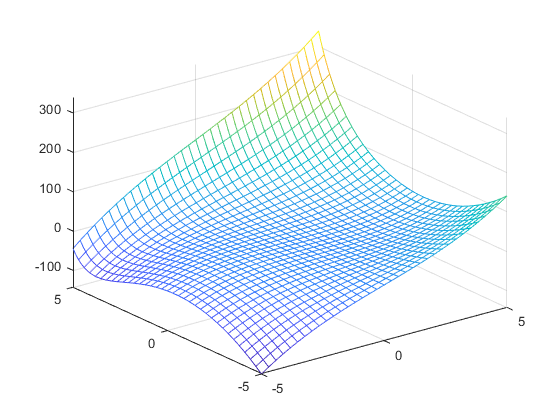

fmesh(eq2)


% 3)
x0=0;y0=0;
U=simplify(int(P,x,x0,x)+int(subs(Q,x,x0),y,y0,y))

$$U = \frac{x^{3}}{3}+\left(y^{2}+y\right)\,x+{\mathrm{e}}^{y}-1$$

syms C
eq2=U==C

$$eq2 = \frac{x^{3}}{3}+\left(y^{2}+y\right)\,x+{\mathrm{e}}^{y}-1=C$$

C1=solve(subs(eq2,[x y],[0 0]),C)

$$C1 = 0$$

eq3=subs(eq2,C,C1)

$$eq3 = \frac{x^{3}}{3}+\left(y^{2}+y\right)\,x+{\mathrm{e}}^{y}-1=0$$